# **Data Generation for Graph Neural Networks**

This is a simple test (possibly 2D steady state) for creating datasets for training Graph Neural Networks with Finite Element Nodes. Requires Matlab PDE toolbox to run. 

Considering a single physics system 


$$$k(\frac{\partial^2 T}{\partial x^2} + \frac{\partial^2 T}{\partial y^2}) + Q = 0$$$


clear;
close all;

%Fixed Material Properties
k = 0.001;
Q = 1;
ta = 300;
hmax = 0.3; %Maximum size of mesh

Generating data with multiple geometries - using the `descg` (alternate way is to use .stl) that save inputs. 

## Generating Rectangle based data

Looping over multiple rectangles to solve in each situation - saved in the variable `u`

n_graphs_per_geom =10;
%Rectangle Loop ~ 20 graphs
% 
% u =createArray(n_graphs_per_geom,1,'struct');
% msh = createArray(n_graphs_per_geom,1,'struct');

u = cell(n_graphs_per_geom,1);
msh = cell(n_graphs_per_geom,1);
DBC_edges = cell(n_graphs_per_geom,1);
NBC_edges = cell(n_graphs_per_geom,1);

for i =1:n_graphs_per_geom
    width = randi([2,5]); 
    height = randi([2,5]);
    
    
    DBC_edges{i} = randi(4,2,1)';%2 DBC edges 
    NBC_edges{i} = setdiff([1,2,3,4],DBC_edges{i});%"rest" are NBC edges

    [model,msh{i}] = rectangle_mesh_model(width,height,hmax);
    R = solve_pde_simple_heat(model,k,Q,ta,DBC_edges{i},NBC_edges{i});

    label = "rectangle";
    u{i} = R.NodalSolution;  
end

Elapsed time is 0.047798 seconds.
Elapsed time is 0.014575 seconds.
Elapsed time is 0.059547 seconds.
Elapsed time is 0.005445 seconds.
Elapsed time is 0.005274 seconds.
Elapsed time is 0.003692 seconds.
Elapsed time is 0.004115 seconds.
Elapsed time is 0.003657 seconds.
Elapsed time is 0.003874 seconds.
Elapsed time is 0.003366 seconds.


## **Just Visualizing the Solutions of Final Geometry Setting**

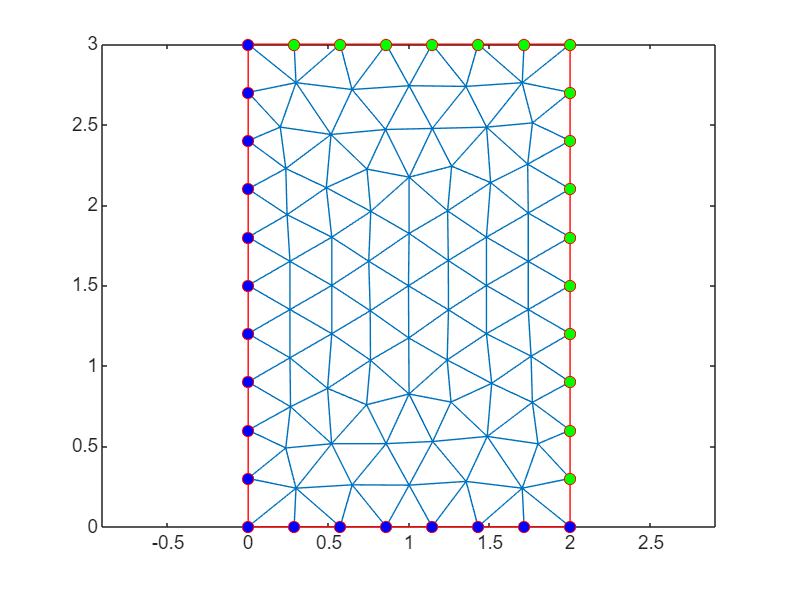

msh_plot = msh{end};
DBC_boundary_indices = findNodes(msh_plot, "region", "Edge",DBC_edges{end});
NBC_boundary_indices = findNodes(msh_plot, "region", "Edge",NBC_edges{end});

figure
pdemesh(model);
hold on
plot(msh_plot.Nodes(1,DBC_boundary_indices),msh_plot.Nodes(2,DBC_boundary_indices),"or","MarkerFaceColor","g");
plot(msh_plot.Nodes(1,NBC_boundary_indices),msh_plot.Nodes(2,NBC_boundary_indices),"or","MarkerFaceColor","b");

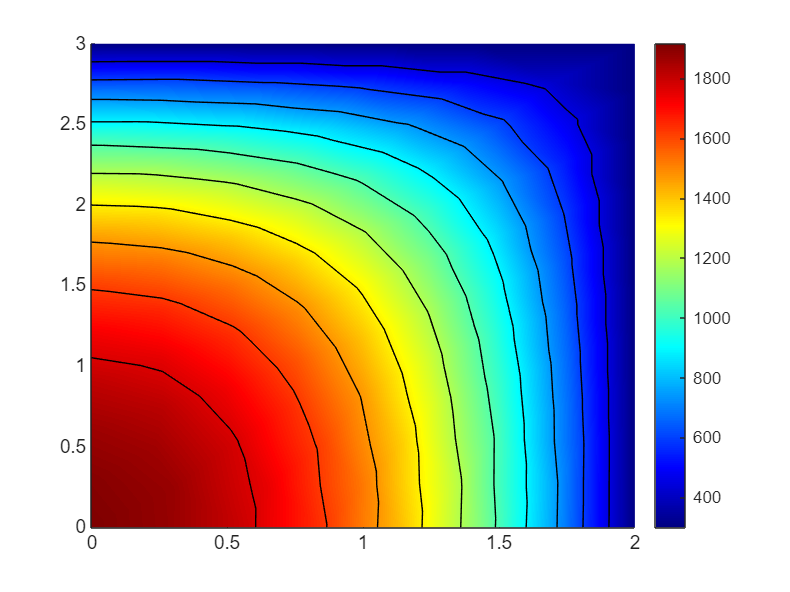

figure;
pdeplot(model,"XYData",u{end},"Contour","on","ColorMap","jet");

## Building Inputs and Outputs for GNNs

The GNNs have input as a graph and output as temperature at all nodes. Note that GNNs can work with varying "sizes" of graphs - i.e., each "graph datapoint" can have different number of nodes and edges. 

The **current idea**

Nodes of Graph - are exactly nodes of Finite Element Method. 

Edges of Graph - Connect only with "neighboring" nodes - With feature as the distance 

                            More *correct *way is possibly to say each "element" is connected. 

**Sizes of node-feature matrix, edge-feature matrix, and adjacency matrix**

*Assume *$n_{nodes}$ 

***Input**** Node-feature Matrix* 

*Features - Only the one-hot vectors (Internal Point, DBC, NBC) *$$\rightarrow$ $n_{nodes} \times 3$$

one_hot_geoms = cell(n_graphs_per_geom,1);

for i =1:n_graphs_per_geom
    DBC_boundary_indices = findNodes(msh{i}, "region", "Edge",DBC_edges{i});
    NBC_boundary_indices = findNodes(msh{i}, "region", "Edge",NBC_edges{i});
    %One-hot encoding
    one_hot_nodes = zeros(3,size(msh{i}.Nodes,1));

    %partially from ChatGPT
    one_hot_nodes(2, DBC_boundary_indices) = 1;
    one_hot_nodes(3, NBC_boundary_indices) = 1;

    internal_indices = setdiff(1:size(msh{i}.Nodes,2), [DBC_boundary_indices, NBC_boundary_indices]);
    one_hot_nodes(1, internal_indices) = 1;

    one_hot_geoms{i} = one_hot_nodes;
end

*Adjacency Matrix **(not needed directly but only as mappings)*

Sparse $n_{nodes} \times n_{nodes}$ - with connections only within elements (all six within an element are interconnected) 

Note: A "Quadratic" element needs three points including the midpoint, so each "triangle" of the mesh has six points.

A "Linear" element needs only two points, so each "triangle" of the mesh has three points.     

The "**Finite Elements**" (in Matlab `msh.Nodes`of size $6 \times n$ for quadratic mesh)

The edge attributes should be a list of all edges as one $\rightarrow$one. 

*Edge-feature Matrix*

Should include only elements that are connected but with distance $\rightarrow$All combo edge distances * Adjacency Matrix 

edge_mappings = cell(n_graphs_per_geom,1);
edge_distances = cell(n_graphs_per_geom,1);

for i =1:n_graphs_per_geom
    mesh_elements = msh{i}.Elements;
    edges = [mesh_elements([1, 2], :), mesh_elements([2, 3], :), mesh_elements([3, 1], :)];
    
    % Ensure each edge is sorted to avoid duplicates
    edges = sort(edges, 1); % Sort node pairs along each column
    
    % Find unique edges
    edge_mappings{i} = unique(edges', 'rows');

    % edge_distances{i} = msh{i}.Nodes(1,i) 

    edge_distances{i} = distance_mesh_nodes(msh{i},edge_mappings{i});
end

***Output**** Node-feature Matrix*

Temperature $\rightarrow$$n_{nodes} \times 1$ - Already Exists in `u`

## Writing Data Set on h5

Writing as `.mat `is the easiest to save "unstructured data" but it might take a lot of time to load the data in Python. 

Current idea is to create one `.h5 `file for every single geometry - i.e., every single graph

%Write as h5 for convenience in Python 
folder = 'C:\Users\rg24o\Documents\M2M Data Globus - B317 PC\GNNs Data Feb 2025\';
filename = strcat(folder,'Initial_test2.h5') ;
% dataset_names = ["/one_hot_features","/edge_mappings","/edge_distance","/Temperature"];
total_n_geoms = n_graphs_per_geom;

sub_group_names = ["/one_hot_features","/edge_mappings","/edge_distance","/Temperature"];

for i = 1:total_n_geoms
    data_i = {one_hot_geoms{i},edge_mappings{i},edge_distances{i},u{i}};
    group_name = ['/graph_' num2str(i)];
    for k = 1:4
        sub_group_name = strcat(group_name,sub_group_names(k));
        h5create(filename, sub_group_name, size(data_i{k}));  % Create dataset
        h5write(filename, sub_group_name, data_i{k});  % Write data as matrix
    end
end



% for k=1:size(data,2)
%     k
%     write_h5(filename,dataset_names(k),data(k),total_n_geoms)
% end







%Input
% input_data = [u,]

**Generating Multiple Geometries**

Generate ~ 80 graphs

Four standard geometries - *Circle, Polygon, Rectangle, and Ellipse *with varying parameters. 

**Circle**

**Testing on Geometries with Complexities? - Generate may be 10 to 20. s**

(Look for some standard .stl files)** - **Look for creating  different geometeries from Matlab Documentation - [https://www.mathworks.com/help/pde/ug/decsg.html](https://www.mathworks.com/help/pde/ug/decsg.html)

*Geometry description matrix, specified as a matrix of double-precision numbers. The number of columns corresponds to the number of shapes used to construct the geometry. Each column in the geometry description matrix corresponds to a shape in the CSG model. The model supports four types of shapes:*

- *For a circle, the first row contains *`1`*. The second and third rows contain the x- and y-coordinates of the center. The fourth row contains the radius of the circle. The radius must be a positive value.*

- *For a polygon, the first row contains *`2`*. The second row contains n, which is the number of line segments in the boundary of the polygon. The next n rows contain the x-coordinates of the starting points of the edges, and the n rows after that contain the y-coordinates of the starting points of the edges.*

- *For a rectangle, the first row contains *`3`*, and the second row contains *`4`*. The next four rows contain the x-coordinates of the starting points of the edges, and the four rows after that contain the y-coordinates of the starting points of the edges.*

- *For an ellipse, the first row contains *`4`*. The second and third rows contain the x- and y-coordinates of the center. The fourth and fifth rows contain positive values, specifying the lengths of the semiaxes of the ellipse. The sixth row contains the rotational angle of the ellipse, measured in radians.*

*All shapes in a geometry description matrix have the same number of rows. Elements of the matrix that are not required to encode information about the corresponding shapes must be set to zero.*


% saveas(gcf,label+"outline.png") #Good to save the plot for
% visualizations

## For Later



% hmax = 0.1; % element size
% msh = generateMesh(model,'Hmax',hmax);
% figure
% pdeplot(model)

Specifying PDE coefficients and Boundaries

I will choose mixed boundaries - Dirchilet and Neumann (No Robin for now). 

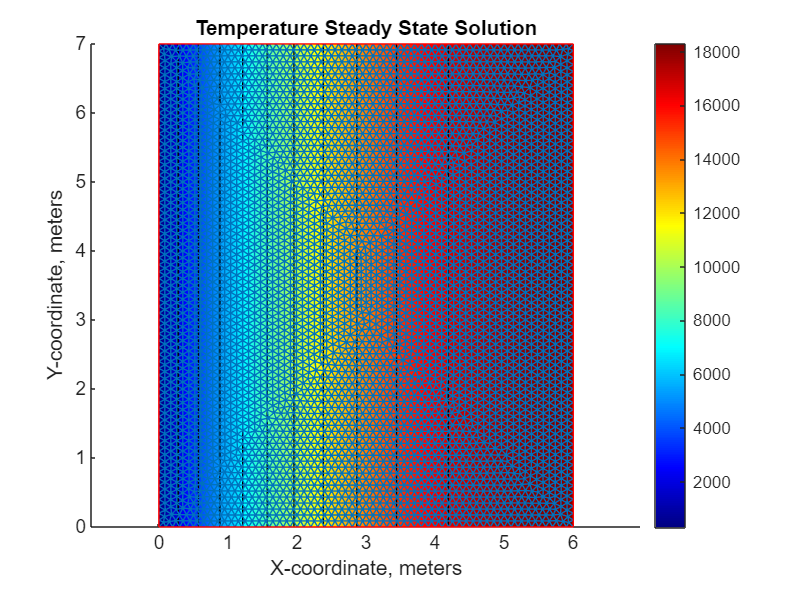

Unrecognized function or variable 'DBC_boundary_indices'.

Solving next.. - also output the computational time. 

Extracting and plotting.. 

Getting the "edges" to form the graph for GNNs - 

using `findNodes` - https://www.mathworks.com/help/pde/ug/pde.femesh.findnodes.html

Make the Nodes as one-hot vector - PDE, DBC, and NBC